Si aparece un error feo pero todo corre la primera vez que corro un mlx, no es nada, es solo que la versión pirata manda error la primera vez.

Las ecuaciones que rigen este problema vienen en el powerpoint de Marcelo, pero vienen del mismo principio de mx'' + bx' + kx = 0 que son las mismas del masaResorte.

# Simulación del péndulo

y = [theta;omega]

## Péndulo sin amortiguación

%Para poner titulos y saltos, en la pestaña de live editor hay section breaks y text.
g = 9.81;
l = 1;
y0 = [pi/8;0];
f = @(t,y) [y(2); -(g/l)*sin(y(1))];
%lo que estoy calculando aquí es la derivada del angulo sobre el tiempo y la derivada de la velocidad sobre 
% el tiempo (recordar que velocidad angular = w).
%Como tal es incorrecto usar y, y0. Debería de ser thetaw, thetaw0.

[t,y] = ivps(f,0,10,y0,0.1,4)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y =     0.3927    0.3741    0.3199    0.2351    0.1277    0.0079   -0.1127   -0.2223   -0.3105   -0.3690   -0.3924   -0.3785   -0.3287   -0.2474   -0.1424   -0.0236    0.0976    0.2092    0.3007    0.3633    0.3914    0.3823    0.3369    0.2594    0.1569    0.0392   -0.0823   -0.1958   -0.2904   -0.3571   -0.3898   -0.3856   -0.3447   -0.2709   -0.1711   -0.0548    0.0669    0.1820    0.2796    0.3503    0.3876    0.3882    0.3519    0.2820    0.1851    0.0703   -0.0513   -0.1680   -0.2684   -0.3430
         0   -0.3697   -0.7058   -0.9766   -1.1549   -1.2218   -1.1700   -1.0052   -0.7449   -0.4155   -0.0483    0.3233    0.6656    0.9464    1.1378    1.2197    1.1832    1.0321    0.7828    0.4607    0.0964   -0.2765   -0.6243   -0.9147   -1.1190   -1.2157   -1.1944   -1.0574   -0.8195   -0.5051   -0.1445    0.2292    0.5821    0.8816    1.0983    1.2097    1.2037    1.0811    0.8549    0.5487    0.1923   -0.1816   -0.5391   -0.8471   -1.0759   -1.2018   -1.2111   -1.1029   -0.8890   -0

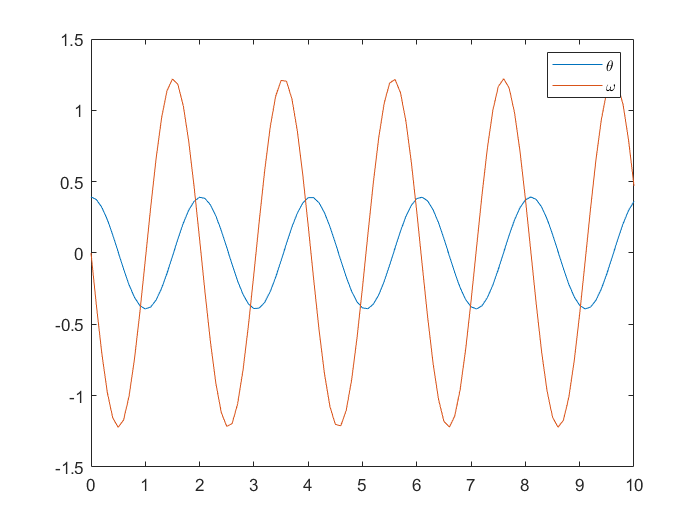

plot(t,y)
legend('\theta', '\omega')

## Pendulo con amortiguación.

d = .01;
f = @(t,y) [y(2); -(g/l)*sin(y(1))-d*y(2)];
y0 = [pi/8;0];

[t,y] = ivps(f,0,20,y0,0.1,4)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y =     0.3927    0.3741    0.3199    0.2352    0.1280    0.0085   -0.1118   -0.2210   -0.3089   -0.3671   -0.3904   -0.3766   -0.3270   -0.2462   -0.1419   -0.0239    0.0963    0.2070    0.2977    0.3597    0.3875    0.3784    0.3334    0.2566    0.1553    0.0390   -0.0810   -0.1929   -0.2862   -0.3519   -0.3840   -0.3796   -0.3392   -0.2665   -0.1682   -0.0538    0.0658    0.1788    0.2744    0.3436    0.3800    0.3802    0.3443    0.2757    0.1806    0.0682   -0.0507   -0.1646   -0.2624   -0.3349
         0   -0.3695   -0.7051   -0.9751   -1.1526   -1.2188   -1.1665   -1.0017   -0.7419   -0.4136   -0.0479    0.3218    0.6619    0.9405    1.1301    1.2107    1.1737    1.0232    0.7755    0.4558    0.0948   -0.2744   -0.6184   -0.9050   -1.1061   -1.2008   -1.1788   -1.0428   -0.8073   -0.4966   -0.1408    0.2274    0.5747    0.8687    1.0808    1.1891    1.1820    1.0603    0.8373    0.5360    0.1858   -0.1809   -0.5309   -0.8317   -1.0543   -1.1758   -1.1832   -1.0759   -0.8654   -0

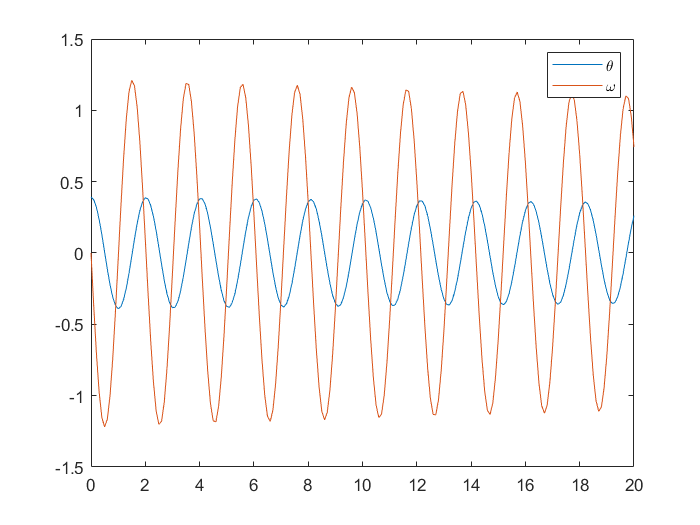

plot(t,y)
legend('\theta', '\omega')

%Si solo quisiera graficar una parte, hago plot(t,y(1,:))